# 무선 신호와 딥러닝을 활용하여 사람 존재 감지하기

- 예제 링크:   [https://kr.mathworks.com/help/wlan/ug/detect-human-presence-using-wlan-signals-and-deep-learning.html](https://kr.mathworks.com/help/wlan/ug/detect-human-presence-using-wlan-signals-and-deep-learning.html)

- USRP device driver 설치 링크:   [https://files.ettus.com/manual/page_install.html](https://files.ettus.com/manual/page_install.html)

### Step 1. SDR Setup

USRP 파라미터를 설정하는 섹션

clc; clear;

% SDR 사용 체크하기
% USRP를 사용할 땐 true로 바꿔준다. false로 하면 이미 모아둔 데이터로 실험할 수 있다
useSDR = true;     

우리가 사용할 SDR의 매개변수를 설정하는 단계

if useSDR
    rxsim.DeviceName    = "B210";          % 오늘 사용할 USRP 제품명: B210
    rxsim.RadioGain     = 15; 
    rxsim.ChannelNumber = 40;               % 여기!!
    rxsim.FrequencyBand = 5;                % 여기!!

    rx = hSDRReceiver(rxsim.DeviceName);
    rx.SampleRate = 20e6; 
    rx.Gain = rxsim.RadioGain;
    rx.CenterFrequency = wlanChannelFrequency(rxsim.ChannelNumber,rxsim.FrequencyBand);
    rx.ChannelMapping = 1;
    rx.OutputDataType = 'single';

    rxsim.SDRObj = rx;
end

Checking radio connections...


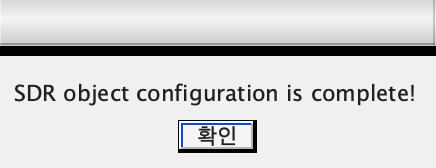



if useSDR %#ok<*UNRCH>
    rxsim.NumCaptures          = 5;    % 여기!!
    rxsim.NumPacketsPerCapture = 8;
    rxsim.BeaconInterval       = 40;   % 여기!!
    rxsim.BeaconSSID           = "TP-Link_E3C5_5G";    % Optional

    % Calculated parameters
    rxsim.CaptureDuration = rxsim.BeaconInterval*milliseconds(1.024)*rxsim.NumPacketsPerCapture + milliseconds(5.5); 

    % SDR setup is complete
    msgbox("SDR object configuration is complete!")
    return
end

### Step 2-1. SDR 사용해 'no-presence' 비콘 패킷 모으기

AP와 USRP 사이, 즉 송신기와 수신기 사이에 사람이 없을 때 비콘 패킷을 송수신하여 Dataset으로 만드는 섹션

Initiating capture 1/5

Initiating capture 1/5 | Capture complete - 2024-02-13 15:31:20 | Processing waveform... | Waveform processing complete.
Initiating capture 2/5 | Capture complete - 2024-02-13 15:31:24 | Processing waveform... | Waveform processing complete.
Initiating capture 3/5 | Capture complete - 2024-02-13 15:31:27 | Processing waveform... | Waveform processing complete.
Initiating capture 4/5 | Capture complete - 2024-02-13 15:31:30 | Processing waveform... | Waveform processing complete.
Initiating capture 5/5 | Capture complete - 2024-02-13 15:31:32 | Processing waveform... | Waveform processing complete.


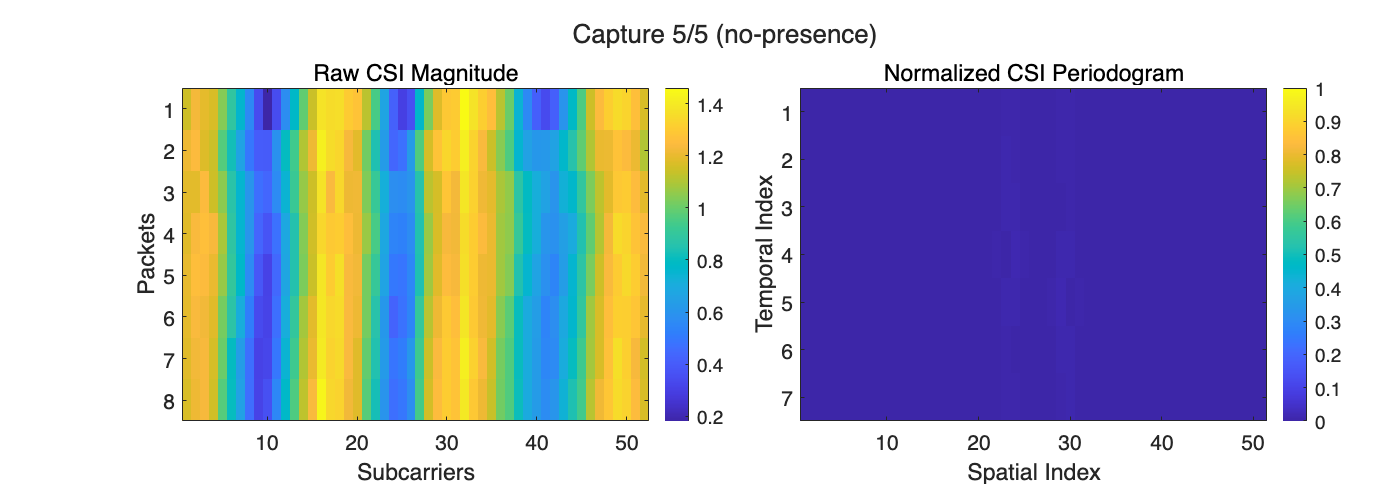

if useSDR   % SDR을 사용해 직접 신호 캡쳐하기
    [dataNoPresence,labelNoPresence,timestampNoPresence] = captureCSIDataset(rxsim,"no-presence");
else        % 아니면 이미 모아둔 데이터 사용하기
    [dataNoPresence,labelNoPresence,timestampNoPresence] = loadCSIDataset("dataset-no-presence.mat","no-presence");
end

### Step 2-2. SDR 사용해 'presence' 신호 데이터 모으기

AP와 USRP 사이, 즉 송신기와 수신기 사이 사람이 있을 때 비콘 패킷을 송수신하여 Dataset으로 만드는 섹션

Initiating capture 1/5 | Capture complete - 2024-02-13 15:31:42 | Processing waveform... | Waveform processing complete.
Initiating capture 2/5

Initiating capture 2/5 | Capture complete - 2024-02-13 15:31:46 | Processing waveform... | Waveform processing complete.
Initiating capture 3/5 | Capture complete - 2024-02-13 15:31:50 | Processing waveform... | Waveform processing complete.
Initiating capture 4/5 | Capture complete - 2024-02-13 15:31:52 | Processing waveform... | Waveform processing complete.
Initiating capture 5/5 | Capture complete - 2024-02-13 15:31:54 | Processing waveform... | Waveform processing complete.


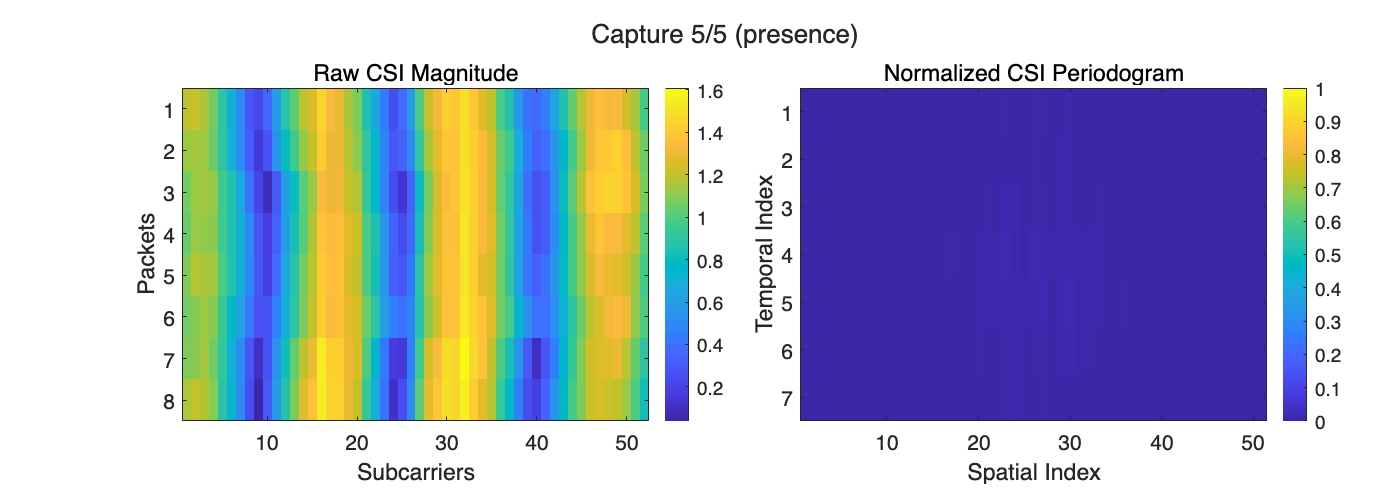

% AP와 USRP 사이 사람이 있을 때 신호를 수신하여 데이터셋으로 만드는 단계

if useSDR   % SDR을 사용해 직접 신호 캡쳐하기
    [dataPresence,labelPresence,timestampPresence] = captureCSIDataset(rxsim,"presence");
else        % 아니면 이미 모아둔 데이터 사용하기
    [dataPresence,labelPresence,timestampPresence] = loadCSIDataset("dataset-presence.mat","presence");
end

### Step 3. CNN 신경망 설계 및 훈련

trainingRatio =  0.8;
numEpochs = 10;
sizeMiniBatch = 8;

[trainingData,validationData,testData,imgInputSize,numClasses] = trainValTestSplit(useSDR,trainingRatio,dataNoPresence,labelNoPresence,dataPresence,labelPresence);

CSI image input size: [51   7]
Number of training images: 8



% 컨볼루션 신경망 구조 정의
cnn = [
    imageInputLayer(imgInputSize,'Normalization','none')
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    dropoutLayer(0.1)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

cnn = layerGraph(cnn);
disp(cnn.Layers)

  다음 계층을 포함한 16×1 Layer 배열:

     1   'imageinput'    영상 입력          51×7×1 영상
     2   'conv_1'        2차원 컨벌루션      8개 3×3 컨벌루션(스트라이드: [1  1], 채우기: 'same')
     3   'batchnorm_1'   배치 정규화        배치 정규화
     4   'relu_1'        ReLU             ReLU
     5   'maxpool_1'     2차원 최댓값 풀링   2×2 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv_2'        2차원 컨벌루션      16개 3×3 컨벌루션(스트라이드: [1  1], 채우기: 'same')
     7   'batchnorm_2'   배치 정규화        배치 정규화
     8   'relu_2'        ReLU             ReLU
     9   'maxpool_2'     2차원 최댓값 풀링   2×2 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv_3'        2차원 컨벌루션      32개 3×3 컨벌루션(스트라이드: [1  1], 채우기: 'same')
    11   'batchnorm_3'   배치 정규화        배치 정규화
    12   'relu_3'        ReLU             ReLU
    13   'dropout'       드롭아웃           10% 드롭아웃
    14   'fc'            완전 연결          2 완전 연결 계층
    15   'softmax'       소프트맥스         소프트맥스
    16   'cla




% Definition of the training options
options = trainingOptions('adam', ...Step 4. 훈련된 CNN 신경망을 사용해 실시간으로 사람 존재 탐지하기
    LearnRateSchedule='piecewise', ...
    InitialLearnRate=0.001, ... % learning rate
    MaxEpochs=numEpochs, ...
    MiniBatchSize=sizeMiniBatch, ...
    ValidationData=validationData, ...
    Shuffle='every-epoch', ...
    ExecutionEnvironment='auto',...
    Verbose=true);


% Train the network
trainedCNN = trainNetwork(trainingData,cnn,options);

단일 CPU에서 훈련합니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　검증　정확도　　｜　　미니　배치　손실　　｜　　검증　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：００　｜　　　　　　６２．５０％　｜　　　５０．００％　｜　　　　　０．６５４９　｜　　０．９９２７　｜　　　０．００１０　｜
｜　　　　　　１０　｜　　　　　　１０　｜　　　　　００：００：０１　｜　　　　　　８７．５０％　｜　　　５０．００％　｜　　　　　０．１７６２　｜　　１．６９２４　｜　　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
훈련 완료: 최대 Epoch가 완료되었습니다.


### Step 4. 훈련된 CNN 신경망을 사용해 실시간으로 사람 존재 탐지하기

만든 CNN 분류 모델에 캡쳐한 패킷을 입력하고,

Presence와 NoPresence 상황을 잘 구분하는지 실험하는 단계

Initiating capture 1/20

Initiating capture 1/20 | Capture complete - 2024-02-13 15:32:16 | Processing waveform... | Waveform processing complete.
Initiating capture 2/20 | Capture complete - 2024-02-13 15:32:20 | Processing waveform... | Waveform processing complete.
Initiating capture 3/20 | Capture complete - 2024-02-13 15:32:24 | Processing waveform... | Waveform processing complete.
Initiating capture 4/20 | Capture complete - 2024-02-13 15:32:27 | Processing waveform... | Waveform processing complete.
Initiating capture 5/20 | Capture complete - 2024-02-13 15:32:31 | Processing waveform... | Waveform processing complete.
Initiating capture 6/20 | Capture complete - 2024-02-13 15:32:34 | Processing waveform... | Waveform processing complete.
Initiating capture 7/20 | Capture complete - 2024-02-13 15:32:36 | Processing waveform... | Waveform processing complete.
Initiating capture 8/20 | Capture complete - 2024-02-13 15:32:39 | Processing waveform... | Waveform processing complete.
Initiating capture 9/20 

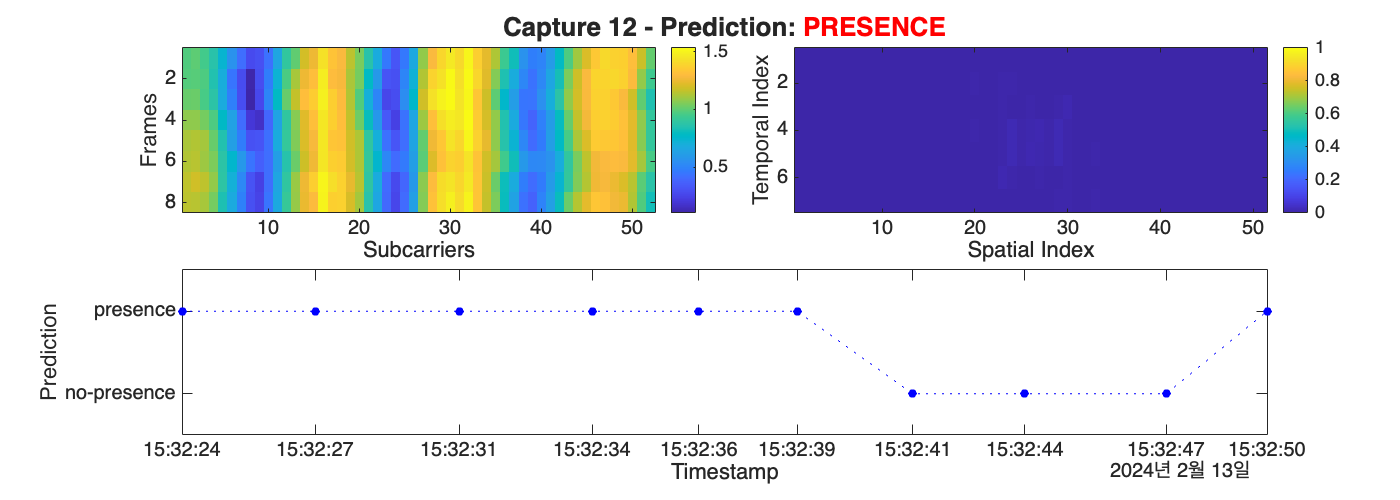

Initiating capture 13/20 | Capture complete - 2024-02-13 15:32:52 | Processing waveform...

if useSDR   % SDR로 캡쳐한 신호로 실험
    sensingResults = livePresenceDetection(rxsim,trainedCNN,20);
else        % 아니면 모아둔 데이터로 실험
    sensingResults = testPresenceDetection(testData,trainedCNN);
end